# Transform World Coordinate Trajectory to Local Trajectory (w.r.t. foot) 

From world coordinates to coordinates robot can understand 

The trajectory of the robot's COM is calculated from the previous script and capture point algorithm. To make this into a useful information robot can understand, we need to transform these points. 

Get data points from the previous script. 

comTrajectory = [hCom.XData; hCom.YData; hCom.ZData; ones(size(hCom.ZData))]; 

ZMP trajectory from previous script 

n = round(desiredStepTime/Ts); 
zmpTrajectory = zeros(size(comTrajectory));
zmpTrajectory(4,:) = 1; 
zmpTrajectory(1, 1) = hZMP.XData(1); 
zmpTrajectory(2, 1) = hZMP.YData(1); 
zmpTrajectory(3, 1) = hZMP.ZData(1);
startingIdx = 2; 
for idx = 1:length(hZMP.XData)
    zmpTrajectory(1, startingIdx:startingIdx + n - 1) = hZMP.XData(idx); 
    zmpTrajectory(2, startingIdx:startingIdx + n - 1) = hZMP.YData(idx); 
    zmpTrajectory(3, startingIdx:startingIdx + n - 1) = hZMP.ZData(idx);
    startingIdx = startingIdx + n; 
end

Transform world coordinate to coordinate w.r.t. foot. Foot is always parallel to the ground and it is pointing downwards like the following. [Muhammad Ali et. all 2010] 

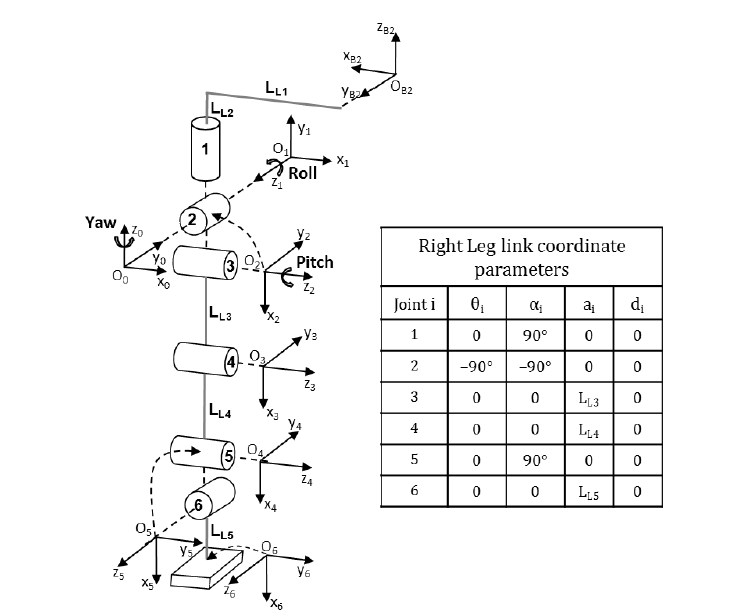

So the transform from robot's body to foot end effector while standing at zModel height is: 

TB_FR = [0 -1 0 0.24/2;0 0 1 0;-1 0 0 -zModel;0 0 0 1];
TB_FL = [0 -1 0 -0.24/2;0 0 1 0;-1 0 0 -zModel;0 0 0 1];

ZMP is the position of the foot, let's take a look at the second portion of the trajectory 

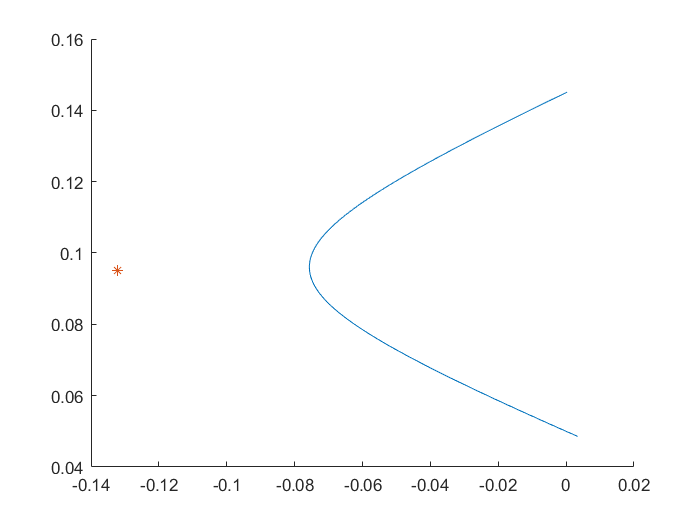

figure 
hold on
startIdx = n + 2; 
endIdx = startIdx + n - 1; 
partialTrajectory = comTrajectory(:,startIdx:endIdx);
partialZMP = zmpTrajectory(:,startIdx:endIdx); 
plot3(partialTrajectory(1,:), partialTrajectory(2,:), partialTrajectory(3,:));
plot3(partialZMP(1,:), partialZMP(2,:), partialZMP(3,:),'*');

Transforming the COM trajectory from global to local coordinates given: Tw_b (partialTrajectory), Tw_fl (partialZMP) 

Tb_fl = Tb_w * Tw_fl; 

Tb_w = Tw_b ^ -1

Tw_b = zeros(4,4,n);
Tw_b(1,1,:) = 1; 
Tw_b(2,2,:) = 1; 
Tw_b(3,3,:) = 1; 
Tw_b(4,4,:) = 1; 
Tw_b(:,4,:) = partialTrajectory; 

Tw_fl = zeros(4,4,n); 
Tw_fl(4,4,:) = 1; 
for idx1 = 1:3
    for idx2 = 1:3
        Tw_fl(idx1,idx2,:) = Tb_fl(idx1,idx2); 
    end
end
Tw_fl(:,4,:) = partialZMP; 

Tb_w = TransformInverse(Tw_b); 
Tb_fl = tmult(Tb_w, Tw_fl); 

simin = timeseries(Tb_fl, 0:Ts:Ts*(n-1)); 


Now run it in KinematicsTest.slx. See if the movement makes sense 

Now that it makes sense, let's create a function to do this transformation given world coordinate of the COM and foot position. 